clear;clc;close all;rng('default');
rng(0);

## 学習用の画像を準備（正常画像のみ）

imdsTrain = imageDatastore('trainingimage','IncludeSubfolders',true);

## Data Augmentationと画像の切り出し

メモリ消費の観点から入力サイズを画像の整数分の１のサイズにしたネットワークを利用するため、学習用にランダムに画像を切り出す機能を利用します。必要に応じてデータ拡張(Augmentation)を適用することもできます。

% augmenter = imageDataAugmenter('RandXReflection',true,'RandYReflection',true);% ,...
% 'RandXTranslation', [-10 10], 'RandYTranslation', [-10 10], 'RandRotation', [-180 180]);
Imgsize = [720 1280];
BlockSize = [240 256];
% 学習時にランダムに画像を切り出して利用
dsTrain = randomPatchExtractionDatastore(imdsTrain,imdsTrain,BlockSize,'PatchesPerImage',16'); % ,'DataAugmentation',augmenter);

## 学習画像の可視化

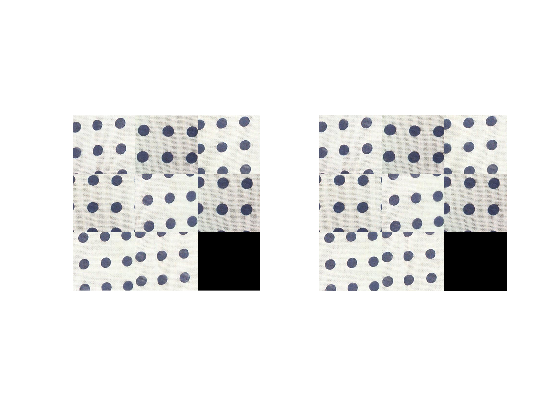

minibatch = preview(dsTrain);
figure,
subplot(1,2,1),montage(minibatch.InputImage);
subplot(1,2,2),montage(minibatch.ResponseImage);shg

## ネットワークの作成

inputsize = [BlockSize 3];
numClasses = 3;
% VGG16ベースのSegNetを定義し最終層を回帰層に変更
lgraph = segnetLayers(inputsize,numClasses,'vgg16');
lgraph = removeLayers(lgraph,{'softmax','pixelLabels'});
lgraph = addLayers(lgraph,regressionLayer('Name','regressionLayer'));
lgraph = connectLayers(lgraph,'decoder1_relu_1','regressionLayer');

## 学習のOption設定

options = trainingOptions('adam', ...
    'InitialLearnRate',20,...
    'MaxEpochs',30, ...
    'Shuffle','never',...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.9, ...
    'LearnRateDropPeriod',5, ...
    'MiniBatchSize',8, ...
    'Plots','training-progress', ...
    'Verbose',false);
dotraining = false;
if dotraining
    % Titan Xにて30分程度かかる
    net = trainNetwork(dsTrain,lgraph,options);
    save('net.mat','net');
else
    load net;
end

## 評価用の画像を準備

imdsTest = imageDatastore('testimage','IncludeSubfolders',true,'LabelSource','foldernames');

## 学習したネットワークで推論する

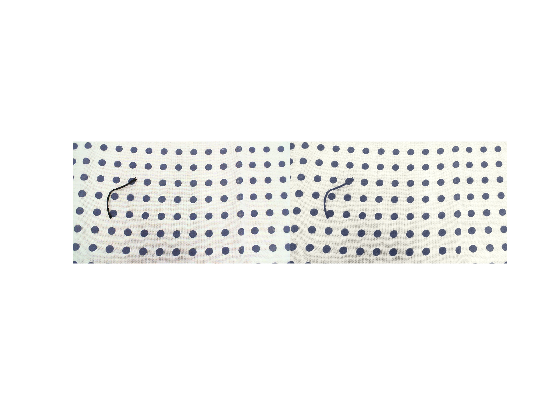

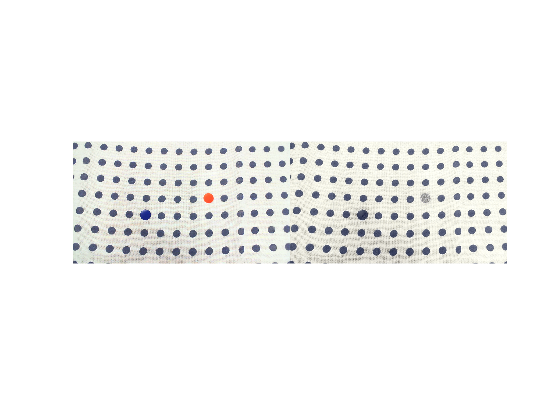

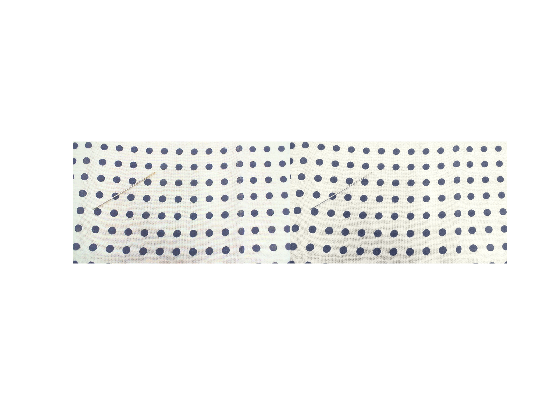

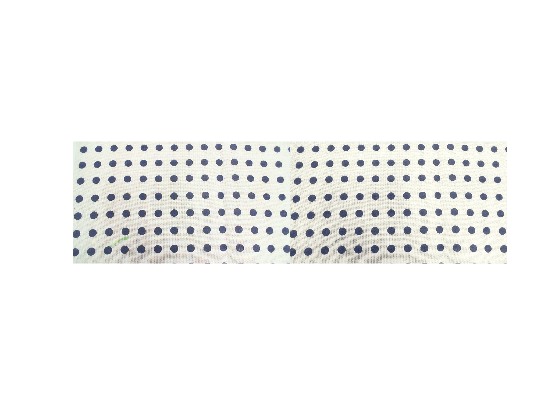

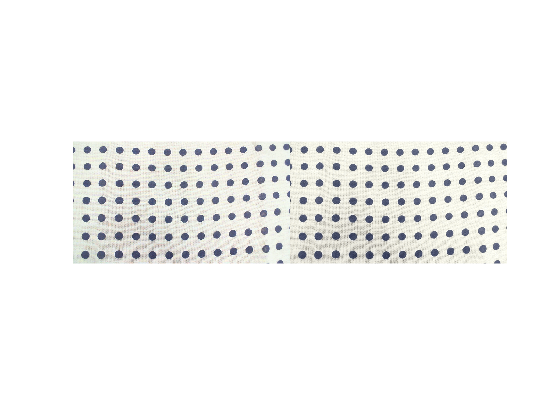

MxN = Imgsize./BlockSize;
% 変数の準備
I_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
Predicted_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
I_big =uint8(zeros(Imgsize(1),Imgsize(2),3));
Predicted_big =uint8(zeros(720,1280,3));
% テスト画像の枚数分処理を行う
for nn=1:numel(imdsTest.Files)
    % 大規模画像のためにブロック単位で処理していく
    I_big = read(imdsTest);
    fun = @(block_struct) predict(net,block_struct.data);
    Predicted_big = uint8(blockproc(I_big,BlockSize,fun));
    % 画像を統合していく
    I_All(:,:,:,nn) = I_big;
    Predicted_All(:,:,:,nn) = Predicted_big;
    % 各入力画像と出力画像を並べて表示する
    figure,imshowpair(I_big,Predicted_big,'montage');shg
end

## データに合わせて評価する

labに変換して差分を評価する

subt = single(rgb2lab(I_All))-single(rgb2lab(Predicted_All));
eval = subt;
% 中央値をゼロ点にして絶対値をとる
evalmed = median(eval,[1 2]);
normeval = abs(eval - evalmed);
% LABそれぞれの誤差を統合する
normeval2 = uint8(squeeze(sum(normeval,3)));

## ノイズを削除し異常を可視化

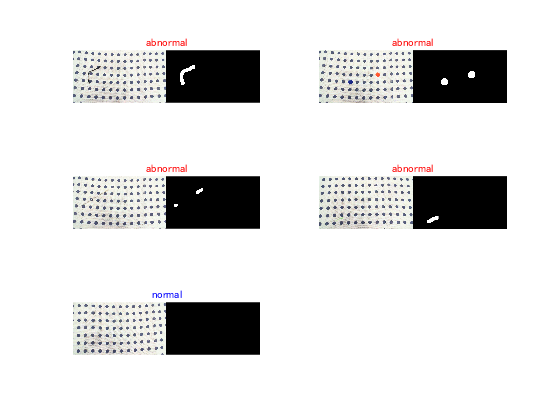

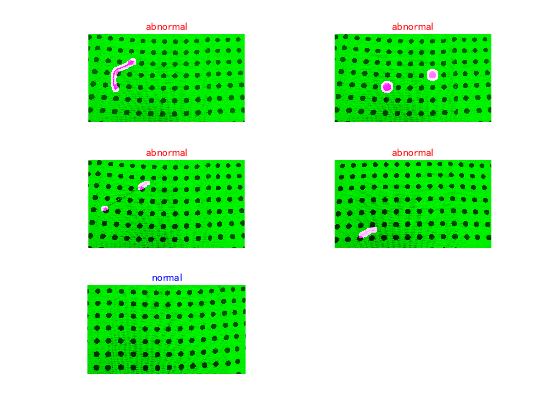

BW = ~(normeval2 < 20);
BW = bwareaopen(BW,50,4);
BW = imdilate(BW,ones(30));
BW = imclearborder(BW,4);
% 表示
Color = {'r','r','r','r','b'};
f1 = figure;
f2 = figure;
for k = 1:numel(imdsTest.Files)
    figure(f1), subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k),'montage');shg
    title(imdsTest.Labels(k),'FontSize',20,'Color', Color{k});
    figure(f2),subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k));shg
    title(imdsTest.Labels(k),'FontSize',20,'Color', Color{k});
end

% _Copyright 2019 The MathWorks, Inc._